close all

filename = 'C:\Users\pyeung\Downloads\HighwayLong3.csv_10.10.10.143_17038.csv';
T = readtable(filename, 'PreserveVariableNames', true);

x = T.("x (m)")

x =    22.0524
   23.4503
   24.6285
   27.7818
   33.4575
   34.4131
   42.9530
   39.6187
   19.2749
   18.6979


y = T.("y (m)")

y =    12.7474
   12.9428
   12.8393
   12.5772
   13.8869
   12.8659
   14.3358
   -2.4615
   -2.1979
   -3.1140


z = T.("z (m)")

z =     2.7009
    2.8733
    3.0191
    3.4082
    4.1057
    4.2240
    5.2731
    4.8646
    2.3667
    2.2959


intens = T.intensity

intens =         8737
        3656
        3897
        5903
        3562
        2823
        3088
        3378
       19899
        5551


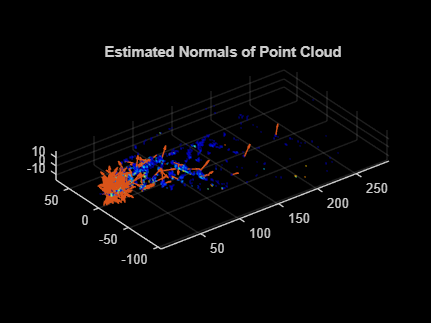

xyz = [x, y, z];

writematrix(xyz,'coordinates.csv')
pc = pointCloud(xyz, 'Intensity', intens);

lower = min([pc.XLimits pc.YLimits]);
upper = max([pc.XLimits pc.YLimits]);

xlimits = [lower upper];
ylimits = [lower upper];
zlimits = pc.ZLimits;

inc = 100;

normals = pcnormals(pc);
x1 = pc.Location(1:inc:end,1);
y1 = pc.Location(1:inc:end,2);
z1 = pc.Location(1:inc:end,3);
u1 = normals(1:inc:end,1);
v1 = normals(1:inc:end,2);
w1 = normals(1:inc:end,3);

writematrix(normals,'normals.csv');

figure
pcshow(pc)
title('Estimated Normals of Point Cloud')
hold on
quiver3(x1,y1,z1,u1,v1,w1);
hold off


writematrix([x1,y1,z1,u1,v1,w1], 'origPc.csv');

## Divide point cloud into cells

index = 1;
incx = 10;
incy = 10;
incz = 10;

r = zeros(size(x, 1),1);

for i = min(pc.XLimits)-1:incx:max(pc.XLimits)
    for j = min(pc.YLimits)-1:incy:max(pc.YLimits)
        for k = min(pc.ZLimits)-1:incz:max(pc.ZLimits)
            indices = x>i & x<=i+incx & y>j & y<=j+incy & z>k & z<=k+incz;
            %size(indices(indices==1))
            r(indices) = index;
            index = index + 1;
        end
    end
end

writematrix(r,'indices.csv');
cmap = jet(index);

## Create new point cloud with averaged normals

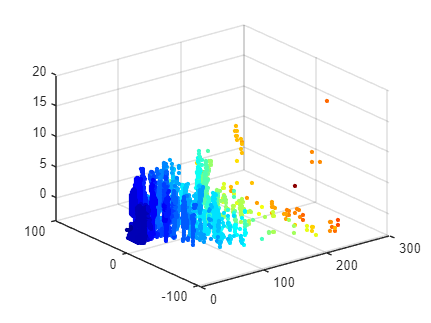

% New point cloud

newPoints = zeros(index,3);

for i = 1:index
    if size(x(r==i),1) > 0
        newPoints(i,1) = mean(x(r==i));
        newPoints(i,2) = mean(y(r==i));
        newPoints(i,3) = mean(z(r==i));
    end
end
figure(), scatter3(x,y,z,10,cmap(r,:),'filled')

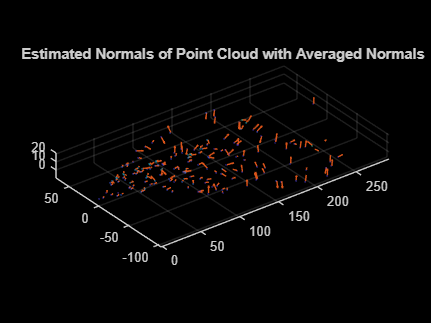


newPc = pointCloud(newPoints);

% New normals

newNormals = zeros(index, 3);

f = 1;

for i = 1:index
    if size(x(r==i),1) > 0
        newNormals(i,1) = f*mean(normals(r==i,1));
        newNormals(i,2) = f*mean(normals(r==i,2));
        newNormals(i,3) = f*mean(normals(r==i,3));
    end
end

x2 = newPc.Location(1:1:end,1);
y2 = newPc.Location(1:1:end,2);
z2 = newPc.Location(1:1:end,3);
u2 = newNormals(1:1:end,1);
v2 = newNormals(1:1:end,2);
w2 = newNormals(1:1:end,3);

writematrix(newNormals, 'newNormals.csv')

figure
pcshow(newPc)
title('Estimated Normals of Point Cloud with Averaged Normals')
hold on
quiver3(x2,y2,z2,u2,v2,w2);
hold off


arr = [x2,y2,z2,u2,v2,w2];

writematrix(arr, 'newPc.csv')

## Scatterplot colored by z component of normal vector

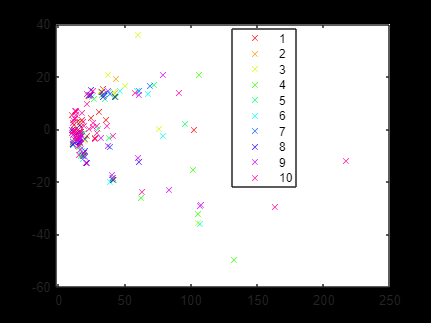

% Old point cloud

arr1 = [x1,y1,z1,u1,v1,w1];

colorvar = zeros(size(arr1,1),1);
index = 1;
low = 2;
inc2 = 0.2;

for i = -1:inc2:1
    colorvar(arr1(:,6) >= i & arr1(:,6) < i + inc2) = index;
    index = index + 1;
end

clr = hsv(length(unique(colorvar(:))));
gscatter(arr1(:,1), arr1(:,2), colorvar(:), clr, 'x')

saveas(gcf,'scatter_orig.png')

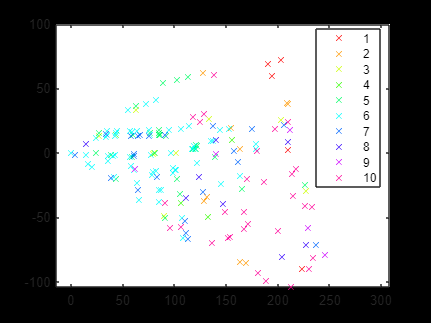


% New point cloud

arr2 = [x2,y2,z2,u2,v2,w2];

colorvar = zeros(size(arr2,1),1);
index = 1;
low = 2;
inc2 = 0.2;

for i = -1:inc2:1
    colorvar(arr2(:,6) >= i & arr2(:,6) < i + inc2) = index;
    index = index + 1;
end

clr = hsv(length(unique(colorvar(:))));
gscatter(arr2(:,1), arr2(:,2), colorvar(:), clr, 'x')

saveas(gcf,'scatter_new.png')